% Define symbolic variables
syms x q P L EI y(x);

% Differential equation
D4y = diff(y, 4);
ode = EI*D4y == q;  % Differential equation for the beam with uniformly distributed load

% Boundary conditions
bc1 = y(0) == 0;  % Deflection is zero at the fixed end
bc2 = subs(diff(y, x), x, 0) == 0;  % Slope is zero at the fixed end
bc3 = subs(diff(y, x, 2), x, L) == 0;  % Bending moment is zero at the free end
bc4 = subs(diff(y, x, 3), x, L) == -P/EI;  % Shear force equals the negative point load at the free end

% Solve the differential equation with boundary conditions
ySol(x) = dsolve(ode, bc1, bc2, bc3, bc4);

% Simplify solution
ySol = simplify(ySol);

% Parameters for plotting (use realistic values for EI, q, P, and L as needed)
EI_value = 1;  % Modulus of elasticity times second moment of area (example value)
q_value = -1;  % Magnitude of the uniformly distributed load (example value)
P_value = -1;   % Magnitude of the point load at the free end (example value)
L_value = 1;  % Length of the beam (example value)

% Define the function for specific values
y_plot(x) = subs(ySol, {EI, q, P, L}, {EI_value, q_value, P_value, L_value});

slope = diff(y_plot,x)

$$slope(x) = -\frac{x^{2}\,\left(2\,x-8\right)}{24}-\frac{x\,\left(x^{2}-8\,x+18\right)}{12}$$


double(y_plot(0.5))

ans = -0.1484

double(y_plot(1))

ans = -0.4583


double(slope(0.5))

ans = -0.5208

double(slope(1))

ans = -0.6667

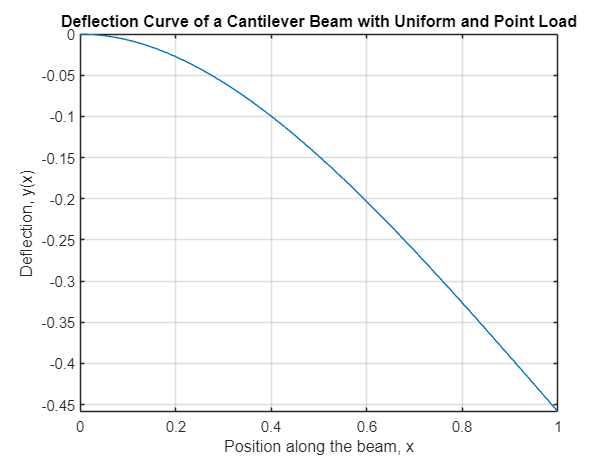



% Plotting the deflection curve
fplot(y_plot, [0 L_value]);
title('Deflection Curve of a Cantilever Beam with Uniform and Point Load');
xlabel('Position along the beam, x');
ylabel('Deflection, y(x)');
grid on;